We use an image that is built into MATLAB.

load mandrill
[m,n] = size(X)

m =    480


n =    500


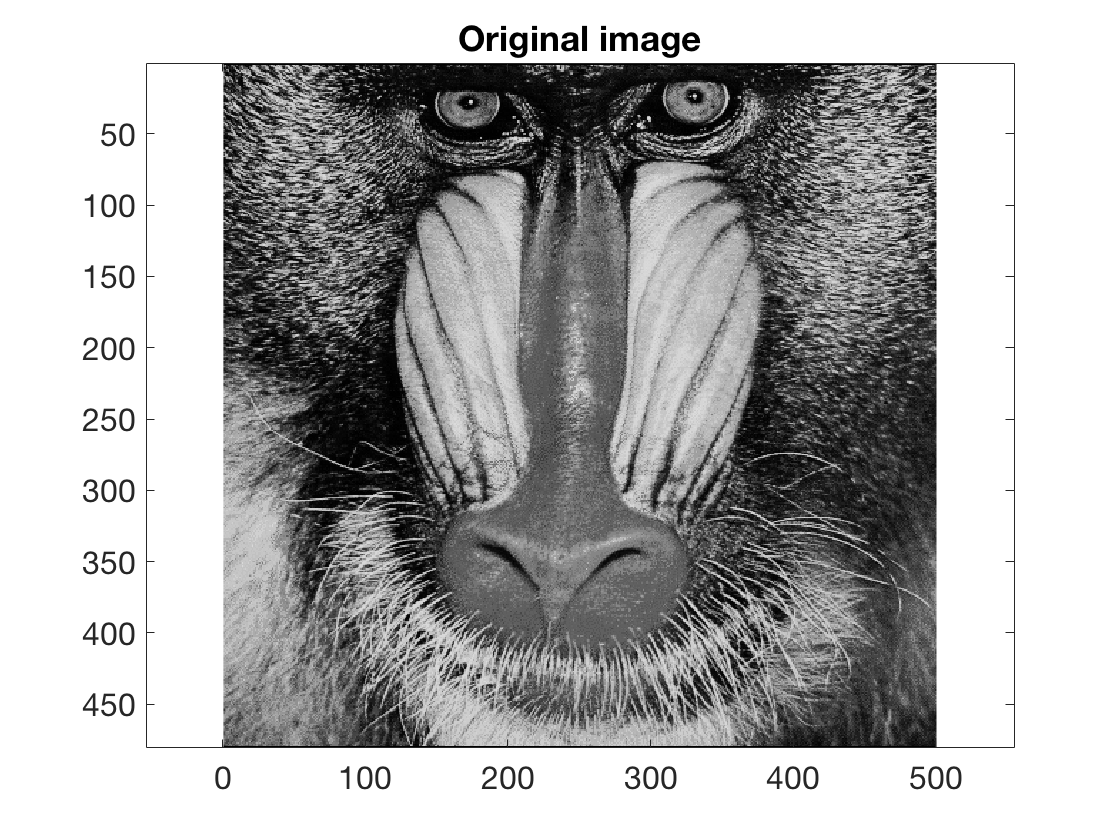

image(X), colormap(gray(256))
axis equal, title('Original image')    % ignore this line

We define the one-dimensional tridiagonal blurring matrices.

v = [1/4 1/2 1/4];
B = spdiags( repmat(v,m,1), -1:1, m,m);
C = spdiags( repmat(v,n,1), -1:1, n,n);

Finally, we show the results of using $k=12$ repetitions of the blur in each direction.

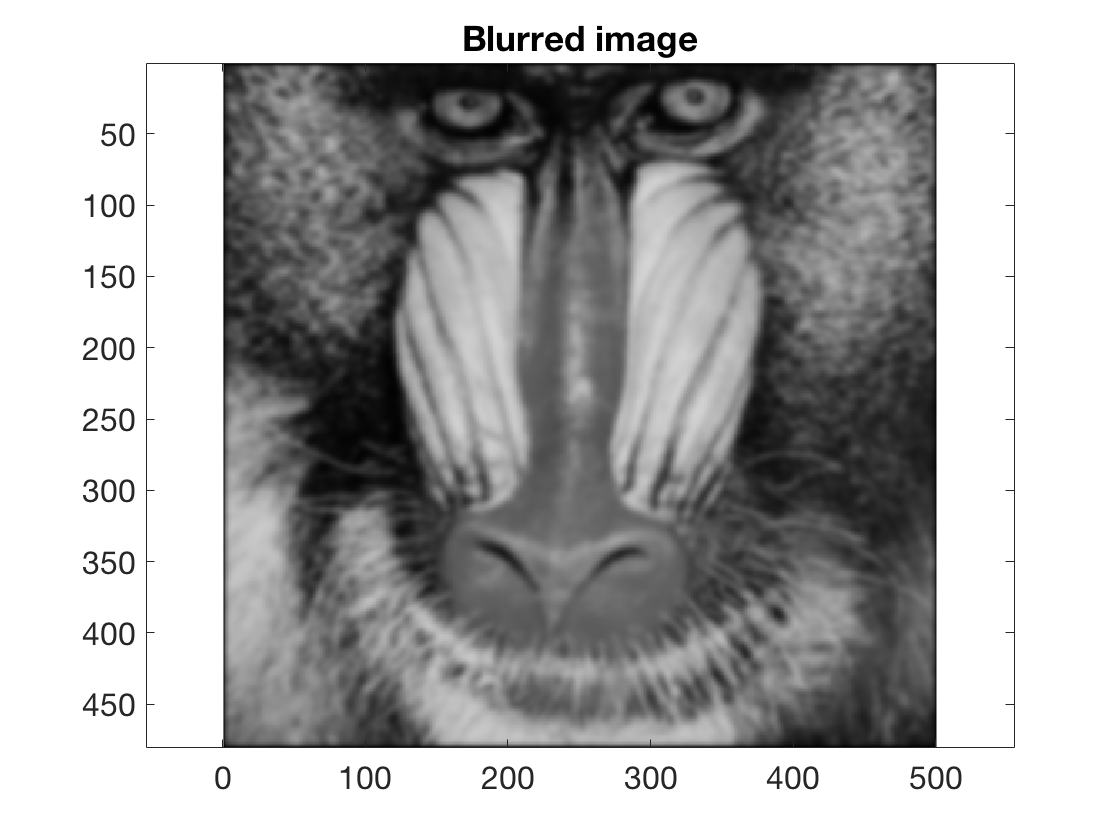

blur = @(X) B^12 * X * C^12;
image(blur(X))
axis equal, title('Blurred image')    % ignore this line